# Basic Information

## Overview

Transmission-line parameters extractor MATLAB implementation of Patent US8892414B1 Author Name: Guorui Wei Created in: 2020-06-04 00:35 Example: Edge-Coupled Surface Microstrip 

clc; clear; close all;

## Import data

% Import simulated data
lineLength = 0.0127; % Line Length(meters)
filename_2line = 'data/2line/2lines_Polar_500mil.s4p';
SingleEnded4PortData = read(rfdata.data,filename_2line);
freq = SingleEnded4PortData.Freq;
freqPts = length(freq);
z0 = SingleEnded4PortData.Z0; % Reference Impedance
numOfLines = size(SingleEnded4PortData.S_Parameters,1)/2;
SingleEnded4PortData.S_Parameters = snp2smp(SingleEnded4PortData.S_Parameters,...
    z0,1:1:2*numOfLines); % Classic style
s_original = SingleEnded4PortData.S_Parameters;

## Add noise to original S-params

% initialize the random number generator to make the results  repeatable.
rng(0,'twister');

noise_mean = 1;   % mean
noise_std = 0.05; % standard deviation
noise_cof_real = noise_std .* randn(size(s_original)) + noise_mean;
noise_cof_imag = noise_std .* randn(size(s_original)) + noise_mean;
s_noisy = real(s_original) .* noise_cof_real                            ...
        + 1i * imag(s_original) .* noise_cof_imag;
rfwrite(sparameters(s_noisy,freq,z0),'data/2line/2lines_noisy_500mil.s4p');

## Load PowerSI extracted noisy-RLGC

Allocate memory

rlgc_noisy_PowerSI.R = zeros(numOfLines,numOfLines,freqPts);
rlgc_noisy_PowerSI.L = rlgc_noisy_PowerSI.R;
rlgc_noisy_PowerSI.C = rlgc_noisy_PowerSI.R;
rlgc_noisy_PowerSI.G = rlgc_noisy_PowerSI.R;
% Load data
filename_PowerSI = 'data/2line/Transmission_RLGC_noisy.csv';
opts = detectImportOptions(filename_PowerSI);
rlgc_PowerSI_mat = readtable(filename_PowerSI);

for freqIdx = 1:freqPts
    for i = 1:numOfLines
        for j = i:numOfLines
            rlgc_noisy_PowerSI.R(i,j,freqIdx) = rlgc_PowerSI_mat{4*freqIdx-3,(2*numOfLines+2-i)*(i-1)/2+j-i+3}/lineLength;
            rlgc_noisy_PowerSI.L(i,j,freqIdx) = rlgc_PowerSI_mat{4*freqIdx-2,(2*numOfLines+2-i)*(i-1)/2+j-i+3}/lineLength;
            rlgc_noisy_PowerSI.G(i,j,freqIdx) = rlgc_PowerSI_mat{4*freqIdx-1,(2*numOfLines+2-i)*(i-1)/2+j-i+3}/lineLength;
            rlgc_noisy_PowerSI.C(i,j,freqIdx) = rlgc_PowerSI_mat{4*freqIdx-0,(2*numOfLines+2-i)*(i-1)/2+j-i+3}/lineLength;
        end
    end
    % RLGC是对称阵
    for i = 1:numOfLines
        for j = i+1:numOfLines
            rlgc_noisy_PowerSI.R(j,i,freqIdx) = rlgc_noisy_PowerSI.R(i,j,freqIdx);
            rlgc_noisy_PowerSI.L(j,i,freqIdx) = rlgc_noisy_PowerSI.L(i,j,freqIdx);
            rlgc_noisy_PowerSI.G(j,i,freqIdx) = rlgc_noisy_PowerSI.G(i,j,freqIdx);
            rlgc_noisy_PowerSI.C(j,i,freqIdx) = rlgc_noisy_PowerSI.C(i,j,freqIdx);
        end
    end
end

## Extract RLGC params using proposed method

rlgc_original = s2rlgc_t(s_original,lineLength,freq,z0,[],false);
rlgc_noisy = s2rlgc_t(s_noisy,lineLength,freq,z0,[],false);

## Smooth test

### R

Rdata_noisy = squeeze(rlgc_noisy.R(1,1,:));

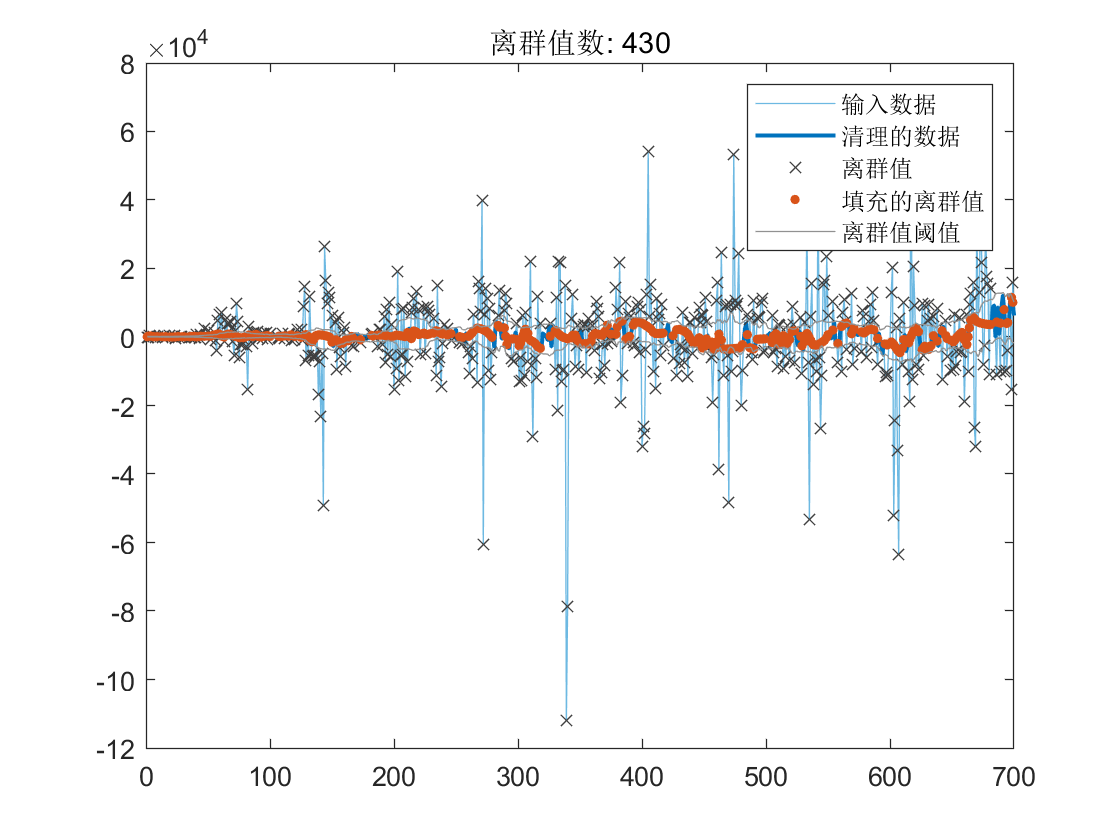

% 填充离群值
[Rdata_cleaned,outlierIndices3,thresholdLow3,thresholdHigh3] = ...
    filloutliers(Rdata_noisy,'pchip','movmedian',50,'ThresholdFactor',0.5);

% 显示结果
clf
plot(Rdata_noisy,'Color',[109 185 226]/255,'DisplayName','输入数据')
hold on
plot(Rdata_cleaned,'Color',[0 114 189]/255,'LineWidth',1.5,'DisplayName','清理的数据')

% 绘制离群值
plot(find(outlierIndices3),Rdata_noisy(outlierIndices3),'x',...
    'Color',[64 64 64]/255,'DisplayName','离群值')
title(['离群值数: ' num2str(nnz(outlierIndices3))])

% 绘制填充的离群值
plot(find(outlierIndices3),Rdata_cleaned(outlierIndices3),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','填充的离群值')

% 绘制离群值阈值
plot([(1:numel(Rdata_noisy))'; missing; (1:numel(Rdata_noisy))'],...
    [thresholdHigh3(:); missing; thresholdLow3(:)],'Color',[145 145 145]/255,...
    'DisplayName','离群值阈值')

hold off
legend

clear outlierIndices3 thresholdLow3 thresholdHigh3

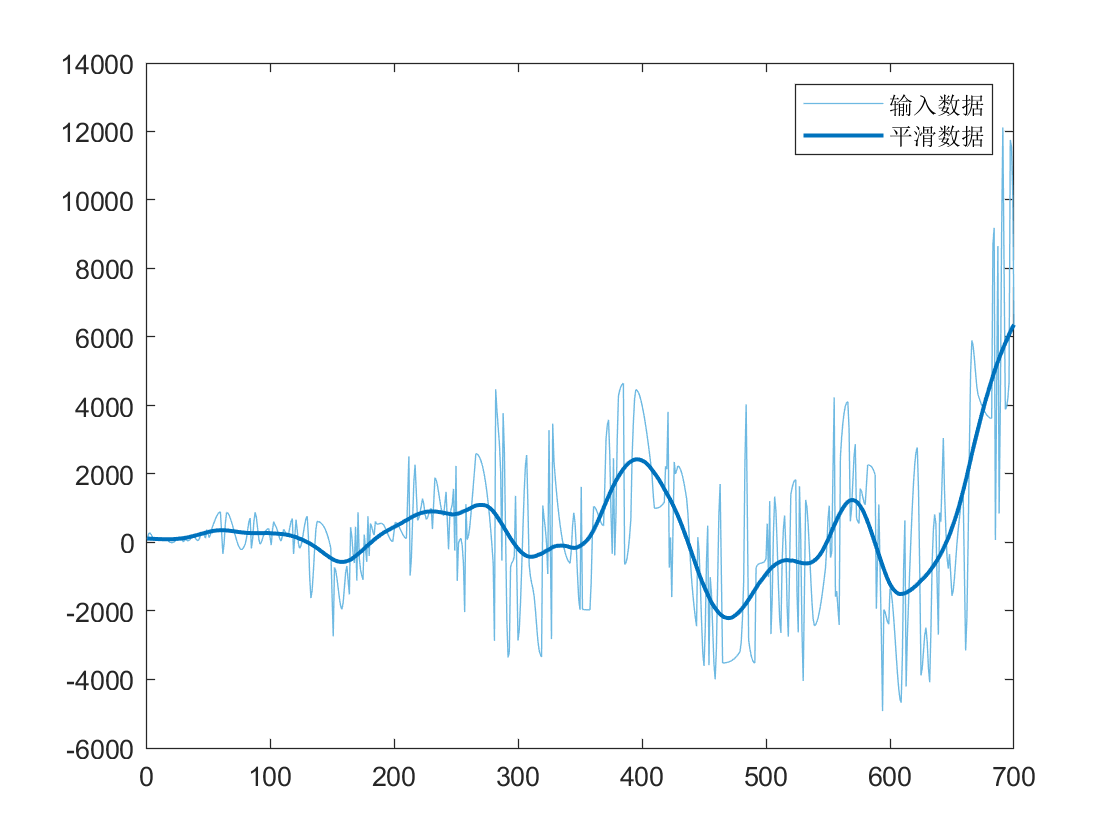

% 对输入数据进行平滑处理
Rdata_smooth = smoothdata(Rdata_cleaned,'gaussian','SmoothingFactor',0.8);

% 显示结果
clf
plot(Rdata_cleaned,'Color',[109 185 226]/255,'DisplayName','输入数据')
hold on
plot(Rdata_smooth,'Color',[0 114 189]/255,'LineWidth',1.5,'DisplayName','平滑数据')
hold off
legend

### L

Ldata_noisy = squeeze(rlgc_noisy.L(1,1,:));

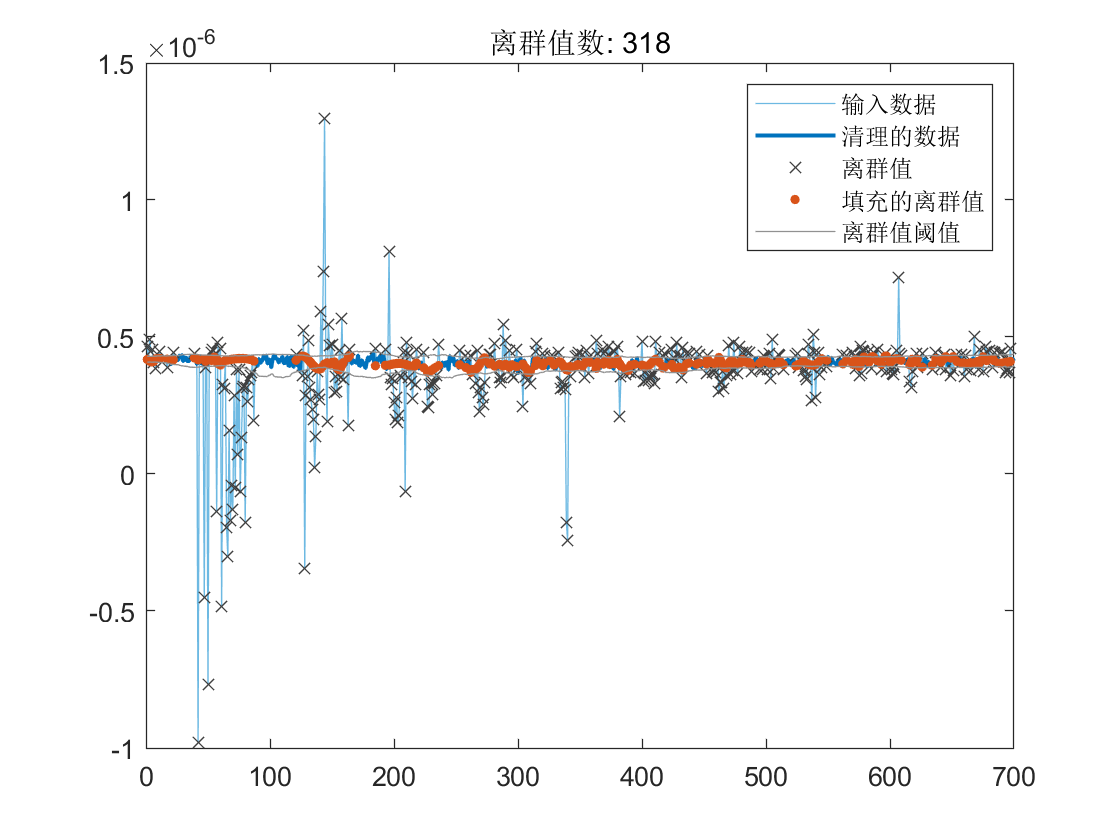

% 填充离群值
[Ldata_cleaned,outlierIndices2,thresholdLow2,thresholdHigh2] = ...
    filloutliers(Ldata_noisy,'makima','movmedian',100,'ThresholdFactor',0.75);

% 显示结果
clf
plot(Ldata_noisy,'Color',[109 185 226]/255,'DisplayName','输入数据')
hold on
plot(Ldata_cleaned,'Color',[0 114 189]/255,'LineWidth',1.5,'DisplayName','清理的数据')

% 绘制离群值
plot(find(outlierIndices2),Ldata_noisy(outlierIndices2),'x',...
    'Color',[64 64 64]/255,'DisplayName','离群值')
title(['离群值数: ' num2str(nnz(outlierIndices2))])

% 绘制填充的离群值
plot(find(outlierIndices2),Ldata_cleaned(outlierIndices2),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','填充的离群值')

% 绘制离群值阈值
plot([(1:numel(Ldata_noisy))'; missing; (1:numel(Ldata_noisy))'],...
    [thresholdHigh2(:); missing; thresholdLow2(:)],'Color',[145 145 145]/255,...
    'DisplayName','离群值阈值')

hold off
legend

clear outlierIndices2 thresholdLow2 thresholdHigh2

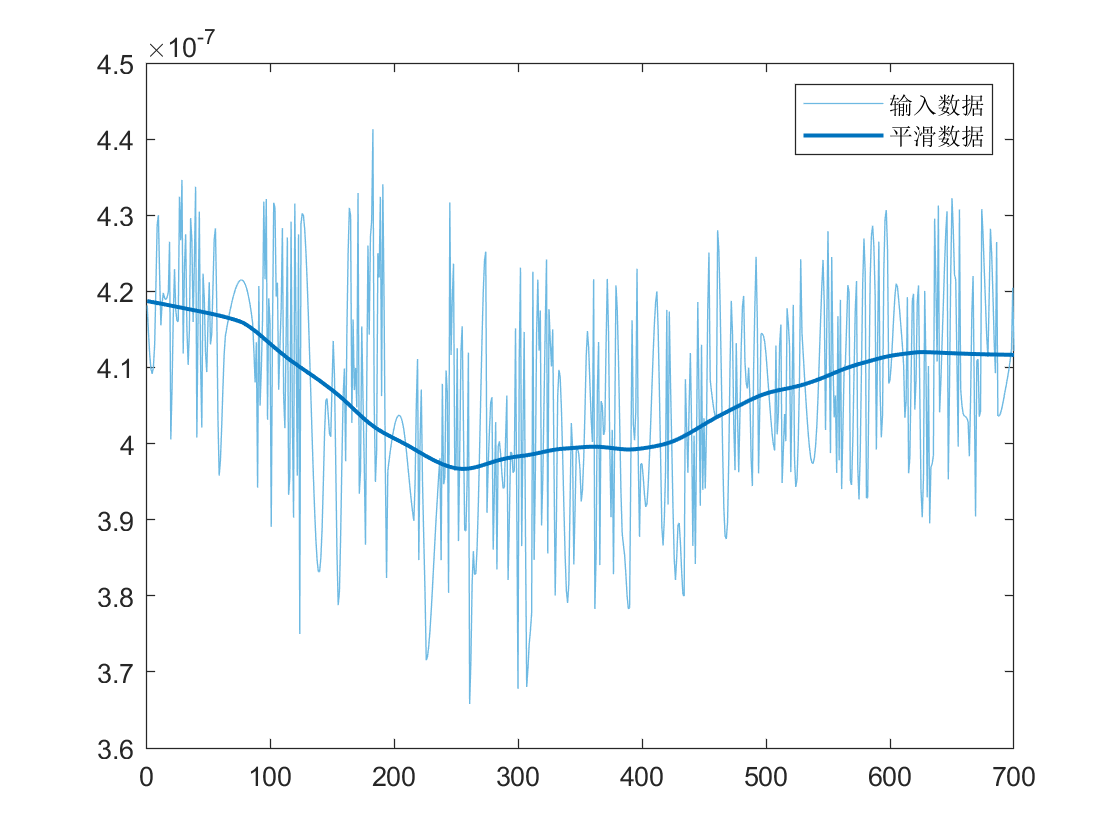

% 对输入数据进行平滑处理
Ldata_smooth = smoothdata(Ldata_cleaned,'rlowess','SmoothingFactor',0.8);

% 显示结果
clf
plot(Ldata_cleaned,'Color',[109 185 226]/255,'DisplayName','输入数据')
hold on
plot(Ldata_smooth,'Color',[0 114 189]/255,'LineWidth',1.5,'DisplayName','平滑数据')
hold off
legend

### G

Gdata_noisy = squeeze(rlgc_noisy.G(1,1,:));

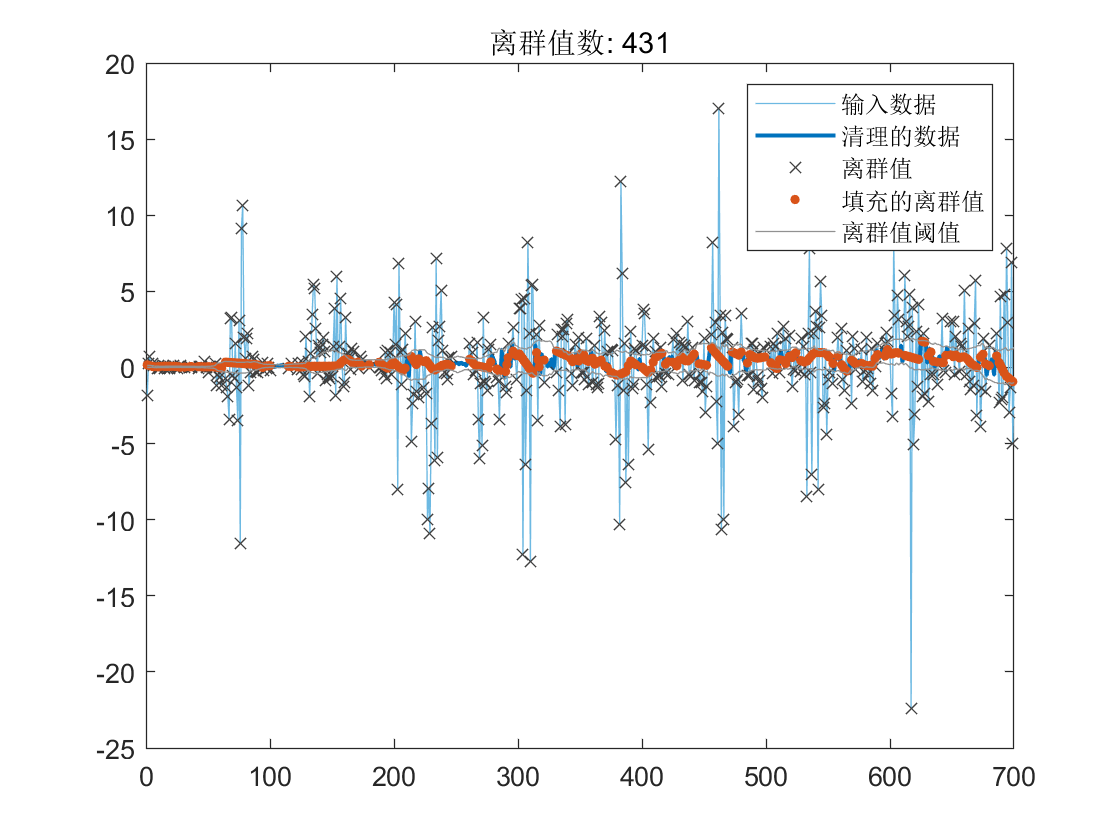

% 填充离群值
[Gdata_cleaned,outlierIndices6,thresholdLow6,thresholdHigh6] = ...
    filloutliers(Gdata_noisy,'linear','movmedian',50,'ThresholdFactor',0.5);

% 显示结果
clf
plot(Gdata_noisy,'Color',[109 185 226]/255,'DisplayName','输入数据')
hold on
plot(Gdata_cleaned,'Color',[0 114 189]/255,'LineWidth',1.5,'DisplayName','清理的数据')

% 绘制离群值
plot(find(outlierIndices6),Gdata_noisy(outlierIndices6),'x',...
    'Color',[64 64 64]/255,'DisplayName','离群值')
title(['离群值数: ' num2str(nnz(outlierIndices6))])

% 绘制填充的离群值
plot(find(outlierIndices6),Gdata_cleaned(outlierIndices6),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','填充的离群值')

% 绘制离群值阈值
plot([(1:numel(Gdata_noisy))'; missing; (1:numel(Gdata_noisy))'],...
    [thresholdHigh6(:); missing; thresholdLow6(:)],'Color',[145 145 145]/255,...
    'DisplayName','离群值阈值')

hold off
legend

clear outlierIndices6 thresholdLow6 thresholdHigh6

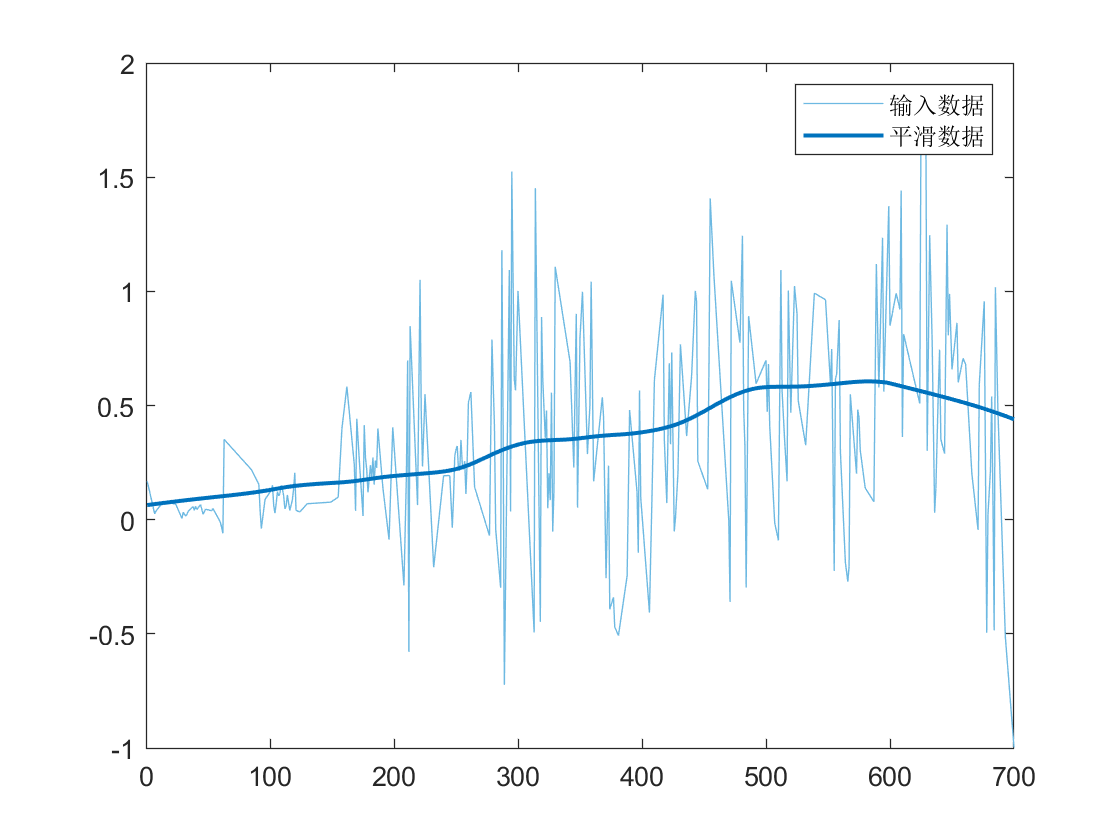

% 对输入数据进行平滑处理
Gdata_smooth = smoothdata(Gdata_cleaned,...
    'rlowess','SmoothingFactor',0.8500000000000001);

% 显示结果
clf
plot(Gdata_cleaned,'Color',[109 185 226]/255,'DisplayName','输入数据')
hold on
plot(Gdata_smooth,'Color',[0 114 189]/255,'LineWidth',1.5,'DisplayName','平滑数据')
hold off
legend

### C

Cdata_noisy = squeeze(rlgc_noisy.C(1,1,:));

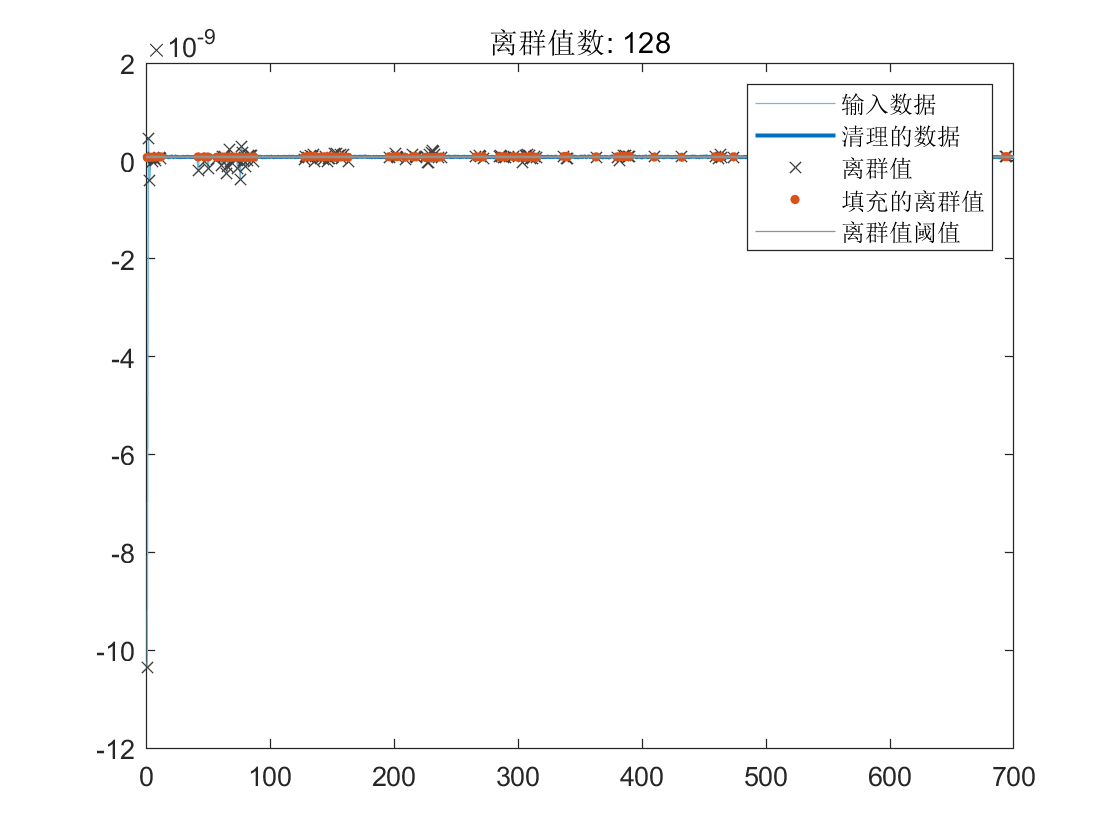

% 填充离群值
[Cdata_cleaned,outlierIndices5,thresholdLow5,thresholdHigh5] = ...
    filloutliers(Cdata_noisy,'linear','quartiles','ThresholdFactor',1);

% 显示结果
clf
plot(Cdata_noisy,'Color',[109 185 226]/255,'DisplayName','输入数据')
hold on
plot(Cdata_cleaned,'Color',[0 114 189]/255,'LineWidth',1.5,'DisplayName','清理的数据')

% 绘制离群值
plot(find(outlierIndices5),Cdata_noisy(outlierIndices5),'x',...
    'Color',[64 64 64]/255,'DisplayName','离群值')
title(['离群值数: ' num2str(nnz(outlierIndices5))])

% 绘制填充的离群值
plot(find(outlierIndices5),Cdata_cleaned(outlierIndices5),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','填充的离群值')

% 绘制离群值阈值
plot([xlim missing xlim],[thresholdLow5*[1 1] NaN thresholdHigh5*[1 1]],...
    'Color',[145 145 145]/255,'DisplayName','离群值阈值')

hold off
legend

clear outlierIndices5 thresholdLow5 thresholdHigh5

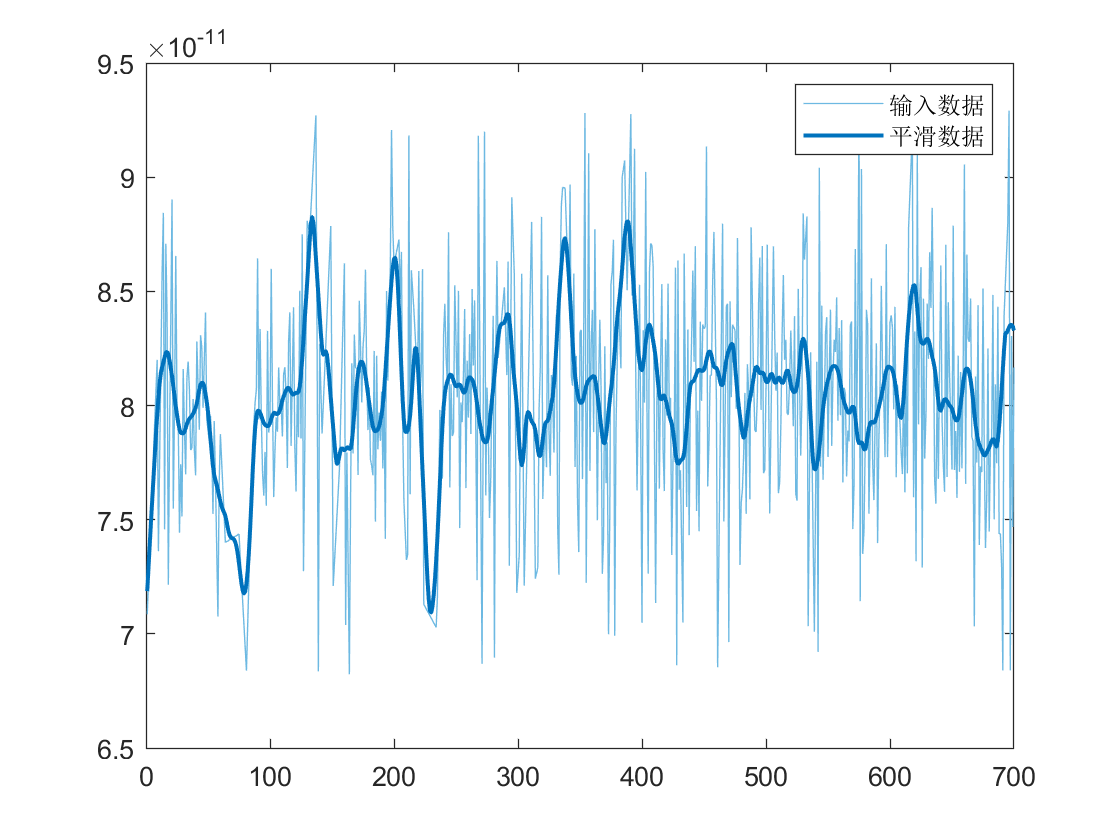

% 对输入数据进行平滑处理
Cdata_smooth = smoothdata(Cdata_cleaned,'rlowess','SmoothingFactor',0.8);

% 显示结果
clf
plot(Cdata_cleaned,'Color',[109 185 226]/255,'DisplayName','输入数据')
hold on
plot(Cdata_smooth,'Color',[0 114 189]/255,'LineWidth',1.5,'DisplayName','平滑数据')
hold off
legend

## Data smooth

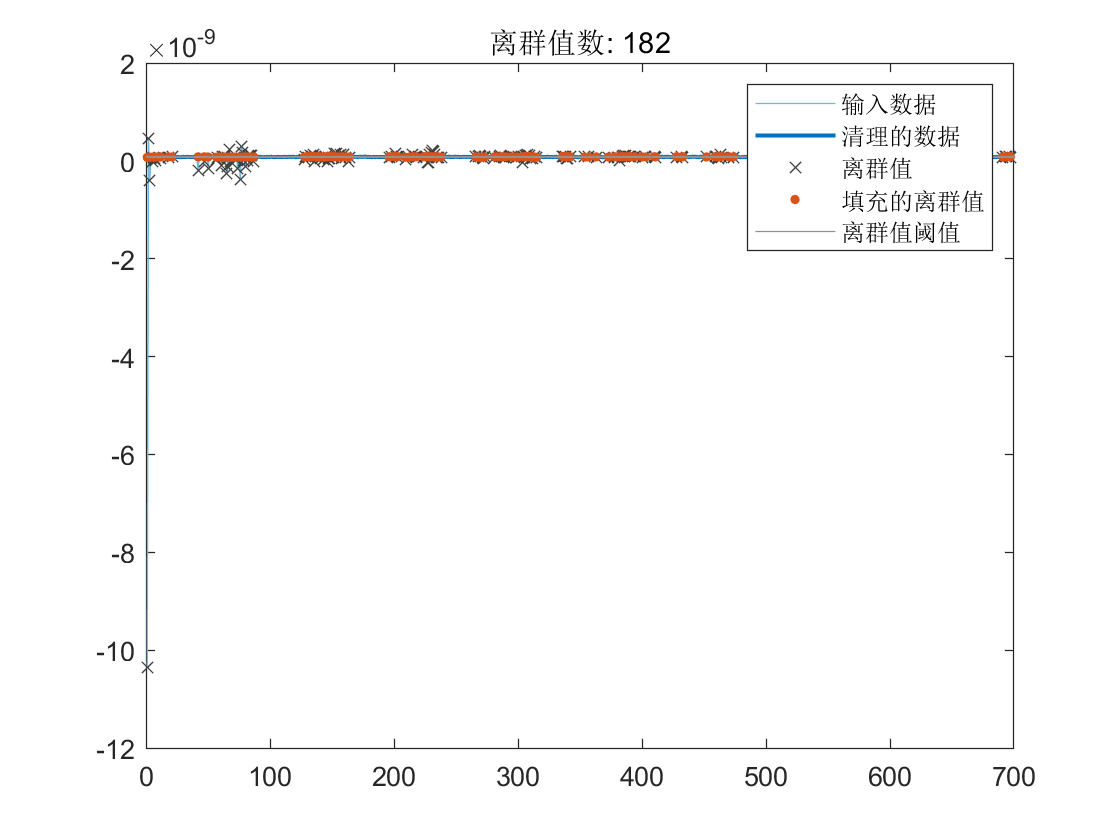

for i = numOfLines:-1:1
    for j = numOfLines:-1:i
        rlgc_smooth.R(i,j,:) = Rsmooth(rlgc_noisy.R(i,j,:));
        rlgc_smooth.L(i,j,:) = Lsmooth(rlgc_noisy.L(i,j,:));
        rlgc_smooth.G(i,j,:) = Gsmooth(rlgc_noisy.G(i,j,:));
        rlgc_smooth.C(i,j,:) = Csmooth(rlgc_noisy.C(i,j,:));
    end
end


for i = numOfLines:-1:1
    for j = numOfLines:-1:i+1
        rlgc_smooth.R(j,i,:) = rlgc_smooth.R(i,j,:);
        rlgc_smooth.L(j,i,:) = rlgc_smooth.L(i,j,:);
        rlgc_smooth.G(j,i,:) = rlgc_smooth.G(i,j,:);
        rlgc_smooth.C(j,i,:) = rlgc_smooth.C(i,j,:);
    end
end

% rlgc_smooth -> s_rlgc_smooth
[s_rlgc_smooth,~] = rlgc2s_t(rlgc_smooth.R,rlgc_smooth.L,rlgc_smooth.G,rlgc_smooth.C,lineLength,freq,z0);

## Check

% 1. rlgc_noisy -> s_extracted_rlgc -> rlgc'
% check_consistence(rlgc_noisy.R, rlgc_noisy.L, rlgc_noisy.G, rlgc_noisy.C, lineLength, freq, z0);
% 2. s_extracted_rlgc -> rlgc' -> s'
[s_extracted_rlgc,~] = rlgc2s_t(rlgc_noisy.R,rlgc_noisy.L,rlgc_noisy.G,rlgc_noisy.C,lineLength,freq,z0);
rlgc_reextract = s2rlgc_t(s_extracted_rlgc,lineLength,freq,z0,[],false);

## Figure

## Comparison between noisy-S (dB) and original-S

% external<-external
figure('Name','noisy-S (dB): See') 
sgtitle({'Comparison Between noisy-S and original-S: See'})
num_of_columes = ceil(numOfLines/2);
for idx = 1:numOfLines
    subplot(2,num_of_columes,idx)
    plot(freq/1e9,db(squeeze(s_noisy(1,idx,:)),'voltage'),'k-')
    hold on
    plot(freq/1e9,db(squeeze(s_original(1,idx,:)),'voltage'),'g--')
    hold off
    grid on
    xlabel('Freq(GHz)');
    ylabel(sprintf('S(1,%u)(dB)',idx));
    title(sprintf('S(1,%u)',idx));
    legend({'noisy','original'},'Location','best','NumColumns',1)
    legend('boxoff')
end

% external<-internal
figure('Name','noisy-S (dB): Sei')
sgtitle({'Comparison Between noisy-S and original-S: Sei'})
num_of_columes = ceil(numOfLines/2);
for idx = 1:numOfLines
    subplot(2,num_of_columes,idx)
    plot(freq/1e9,db(squeeze(s_noisy(1,idx+numOfLines,:)),'voltage'),'k-')
    hold on
    plot(freq/1e9,db(squeeze(s_original(1,idx+numOfLines,:)), 'voltage'),'g--')
    hold off
    grid on
    xlabel('Freq(GHz)');
    ylabel(sprintf('S(1,%u)(dB)',idx+numOfLines));
    title(sprintf('S(1,%u)',idx+numOfLines));
    legend({'noisy','original'},'Location','best','NumColumns',1)
    legend('boxoff')
end

% internal<-external
figure('Name','noisy-S (dB): Sie') 
sgtitle({'Comparison Between noisy-S and original-S: Sie'})
num_of_columes = ceil(numOfLines/2);
for idx = 1:numOfLines
    subplot(2,num_of_columes,idx)
    plot(freq/1e9,db(squeeze(s_noisy(numOfLines+1,idx,:)),'voltage'),'k-')
    hold on
    plot(freq/1e9,db(squeeze(s_original(numOfLines+1,idx,:)),'voltage'),'g--')
    hold off
    grid on
    xlabel('Freq(GHz)');
    ylabel(sprintf('S(%u,%u)(dB)',numOfLines+1,idx));
    title(sprintf('S(%u,%u)',numOfLines+1,idx));
    legend({'noisy','original'},'Location','best','NumColumns',1)
    legend('boxoff')
end

% internal<-internal
figure('Name','noisy-S (dB): Sii') 
sgtitle({'Comparison Between noisy-S and original-S: Sii'})
num_of_columes = ceil(numOfLines/2);
for idx = 1:numOfLines
    subplot(2,num_of_columes,idx)
    plot(freq/1e9,db(squeeze(s_noisy(numOfLines+1,numOfLines+idx,:)),'voltage'),'k-')
    hold on
    plot(freq/1e9,db(squeeze(s_original(numOfLines+1,numOfLines+idx,:)),'voltage'),'g--')
    hold off
    grid on
    xlabel('Freq(GHz)');
    ylabel(sprintf('S(%u,%u)(dB)',numOfLines+1,numOfLines+idx));
    title(sprintf('S(%u,%u)',numOfLines+1,numOfLines+idx));
    legend({'noisy','original'},'Location','best','NumColumns',1)
    legend('boxoff')
end

## Comparison between noisy-S (phase) and original-S

% external<-external
figure('Name','noisy-S (phase): See') 
sgtitle({'Comparison Between noisy-S and original-S: See'})
num_of_columes = ceil(numOfLines/2);
for idx = 1:numOfLines
    subplot(2,num_of_columes,idx)
    plot(freq/1e9,angle(squeeze(s_noisy(1,idx,:))),'k-')
    hold on
    plot(freq/1e9,angle(squeeze(s_original(1,idx,:))),'g--')
    hold off
    grid on
    xlabel('Freq(GHz)');
    ylabel(sprintf('S(1,%u) (rad)',idx));
    title(sprintf('S(1,%u)',idx));
    legend({'noisy','original'},'Location','best','NumColumns',1)
    legend('boxoff')
end

% external<-internal
figure('Name','noisy-S (phase): Sei')
sgtitle({'Comparison Between noisy-S and original-S: Sei'})
num_of_columes = ceil(numOfLines/2);
for idx = 1:numOfLines
    subplot(2,num_of_columes,idx)
    plot(freq/1e9,angle(squeeze(s_noisy(1,idx+numOfLines,:))),'k-')
    hold on
    plot(freq/1e9,angle(squeeze(s_original(1,idx+numOfLines,:))),'g--')
    hold off
    grid on
    xlabel('Freq(GHz)');
    ylabel(sprintf('S(1,%u) (rad)',idx+numOfLines));
    title(sprintf('S(1,%u)',idx+numOfLines));
    legend({'noisy','original'},'Location','best','NumColumns',1)
    legend('boxoff')
end

% internal<-external
figure('Name','noisy-S (phase): Sie') 
sgtitle({'Comparison Between noisy-S and original-S: Sie'})
num_of_columes = ceil(numOfLines/2);
for idx = 1:numOfLines
    subplot(2,num_of_columes,idx)
    plot(freq/1e9,angle(squeeze(s_noisy(numOfLines+1,idx,:))),'k-')
    hold on
    plot(freq/1e9,angle(squeeze(s_original(numOfLines+1,idx,:))),'g--')
    hold off
    grid on
    xlabel('Freq(GHz)');
    ylabel(sprintf('S(%u,%u) (rad)',numOfLines+1,idx));
    title(sprintf('S(%u,%u)',numOfLines+1,idx));
    legend({'noisy','original'},'Location','best','NumColumns',1)
    legend('boxoff')
end

% internal<-internal
figure('Name','noisy-S (phase): Sii') 
sgtitle({'Comparison Between noisy-S and original-S: Sii'})
num_of_columes = ceil(numOfLines/2);
for idx = 1:numOfLines
    subplot(2,num_of_columes,idx)
    plot(freq/1e9,angle(squeeze(s_noisy(numOfLines+1,numOfLines+idx,:))),'k-')
    hold on
    plot(freq/1e9,angle(squeeze(s_original(numOfLines+1,numOfLines+idx,:))),'g--')
    hold off
    grid on
    xlabel('Freq(GHz)');
    ylabel(sprintf('S(%u,%u) (rad)',numOfLines+1,numOfLines+idx));
    title(sprintf('S(%u,%u)',numOfLines+1,numOfLines+idx));
    legend({'noisy','original'},'Location','best','NumColumns',1)
    legend('boxoff')
end

## Reconstruct noisy S using powerSI-noisy RLGC

结论：与原始S参数高度一致。用重建S参数再提取RLGC，此RLGC可以准确恢复重建S参数。 说明PowerSI是对原始S参数作了前处理

[s_rlgc_noisy_PowerSI,~] = rlgc2s_t(rlgc_noisy_PowerSI.R,rlgc_noisy_PowerSI.L,rlgc_noisy_PowerSI.G,rlgc_noisy_PowerSI.C,lineLength,freq,z0);
% external<-external
figure('Name','Rebuilt S (using PowerSI-RLGC): See') 
sgtitle({'Comparison Between Calculated S-parameters using';'PowerSI-RLGC and Original S-parameters: See'})
num_of_columes = ceil(numOfLines/2);
for idx = 1:numOfLines
    subplot(2,num_of_columes,idx)
    plot(freq/1e9,db(squeeze(s_rlgc_noisy_PowerSI(1,idx,:)),'voltage'),'k-')
    hold on
    plot(freq/1e9,db(squeeze(s_noisy(1,idx,:)),'voltage'),'g--')
    hold off
    grid on
    xlabel('Freq(GHz)');
    ylabel(sprintf('S1%u(Ohms/m)',idx));
    title(sprintf('S1%u',idx));
    legend({'PowerSI-RLGC','Original S-parameters'},'Location','best','NumColumns',1)
    legend('boxoff')
end

% external<-internal
figure('Name','Rebuilt S (using PowerSI-RLGC): Sei')
sgtitle({'Comparison Between Calculated S-parameters using';'PowerSI-RLGC and Original S-parameters: Sei'})
num_of_columes = ceil(numOfLines/2);
for idx = 1:numOfLines
    subplot(2,num_of_columes,idx)
    plot(freq/1e9,db(squeeze(s_rlgc_noisy_PowerSI(1,idx+numOfLines,:)),'voltage'),'k-')
    hold on
    plot(freq/1e9,db(squeeze(s_noisy(1,idx+numOfLines,:)), 'voltage'),'g--')
    hold off
    grid on
    xlabel('Freq(GHz)');
    ylabel(sprintf('S1%u(dB)',idx+numOfLines));
    title(sprintf('S1%u',idx+numOfLines));
    legend({'PowerSI-RLGC','Original S-parameters'},'Location','best','NumColumns',1)
    legend('boxoff')
end

% internal<-external
figure('Name','Rebuilt S (using PowerSI-RLGC): Sie') 
sgtitle({'Comparison Between Calculated S-parameters using';'PowerSI-RLGC and Original S-parameters: Sie'})
num_of_columes = ceil(numOfLines/2);
for idx = 1:numOfLines
    subplot(2,num_of_columes,idx)
    plot(freq/1e9,db(squeeze(s_rlgc_noisy_PowerSI(numOfLines+1,idx,:)),'voltage'),'k-')
    hold on
    plot(freq/1e9,db(squeeze(s_noisy(numOfLines+1,idx,:)),'voltage'),'g--')
    hold off
    grid on
    xlabel('Freq(GHz)');
    ylabel(sprintf('S%u%u(Ohms/m)',numOfLines+1,idx));
    title(sprintf('S%u%u',numOfLines+1,idx));
    legend({'PowerSI-RLGC','Original S-parameters'},'Location','best','NumColumns',1)
    legend('boxoff')
end

% internal<-internal
figure('Name','Rebuilt S (using PowerSI-RLGC): Sii') 
sgtitle({'Comparison Between Calculated S-parameters using';'PowerSI-RLGC and Original S-parameters: Sii'})
num_of_columes = ceil(numOfLines/2);
for idx = 1:numOfLines
    subplot(2,num_of_columes,idx)
    plot(freq/1e9,db(squeeze(s_rlgc_noisy_PowerSI(numOfLines+1,numOfLines+idx,:)),'voltage'),'k-')
    hold on
    plot(freq/1e9,db(squeeze(s_noisy(numOfLines+1,numOfLines+idx,:)),'voltage'),'g--')
    hold off
    grid on
    xlabel('Freq(GHz)');
    ylabel(sprintf('S%u%u(Ohms/m)',numOfLines+1,numOfLines+idx));
    title(sprintf('S%u%u',numOfLines+1,numOfLines+idx));
    legend({'PowerSI-RLGC','Original S-parameters'},'Location','best','NumColumns',1)
    legend('boxoff')
end


## noisy-RLGC compared with Cadence PowerSI

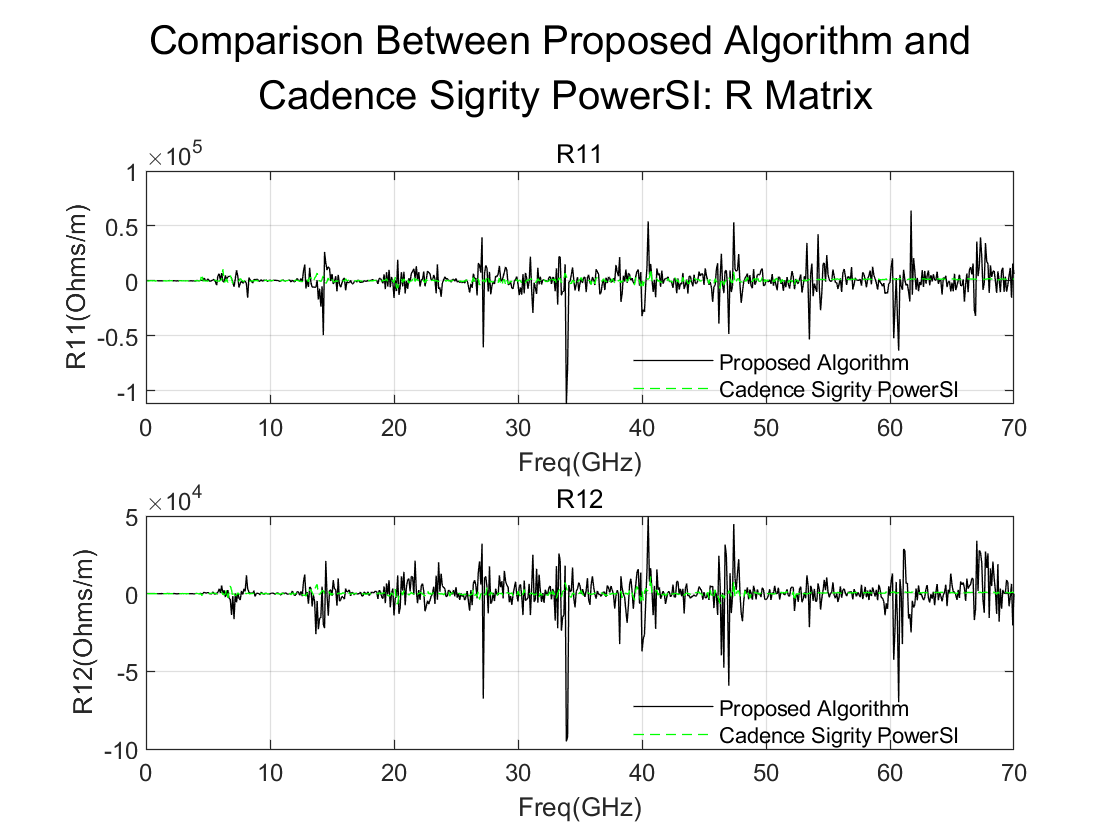

% R
figure('Name','R_noisy (compared with PowerSI)')
sgtitle({'Comparison Between Proposed Algorithm and';' Cadence Sigrity PowerSI: R Matrix'})
total = ceil(numOfLines/2);
for idx = 1:numOfLines
    subplot(2,total,idx)
    plot(freq/1e9,squeeze(rlgc_noisy.R(1,idx,:)),'k-')
    hold on
    plot(freq/1e9,squeeze(rlgc_noisy_PowerSI.R(1,idx,:)),'g--')
    hold off
    grid on
    xlabel('Freq(GHz)');
    ylabel(sprintf('R1%u(Ohms/m)',idx));
    title(sprintf('R1%u',idx));
    legend({'Proposed Algorithm','Cadence Sigrity PowerSI'},'Location','best','NumColumns',1)
    legend('boxoff')
end

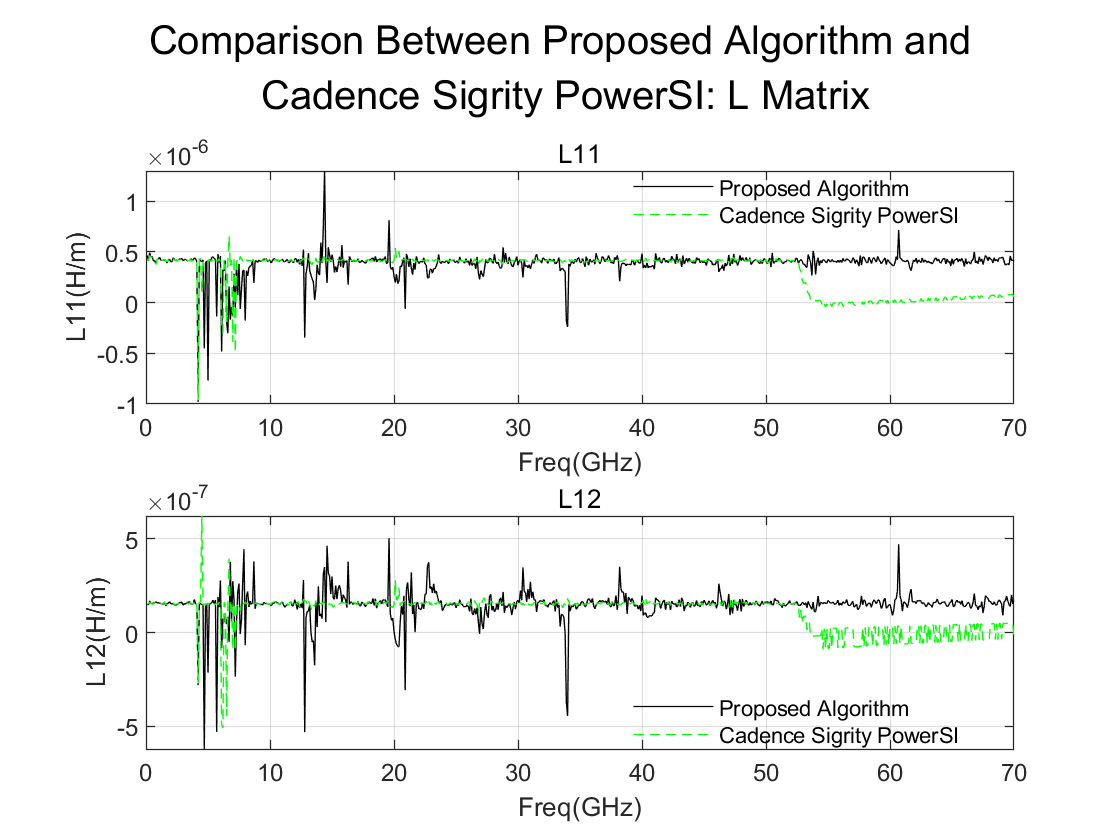


% L
figure('Name','L_noisy (compared with PowerSI)')
sgtitle({'Comparison Between Proposed Algorithm and';' Cadence Sigrity PowerSI: L Matrix'})
total = ceil(numOfLines/2);
for idx = 1:numOfLines
    subplot(2,total,idx)
    plot(freq/1e9,squeeze(rlgc_noisy.L(1,idx,:)),'k-')
    hold on
    plot(freq/1e9,squeeze(rlgc_noisy_PowerSI.L(1,idx,:)),'g--')
    hold off
    grid on
    xlabel('Freq(GHz)');
    ylabel(sprintf('L1%u(H/m)',idx));
    title(sprintf('L1%u',idx));
    legend({'Proposed Algorithm','Cadence Sigrity PowerSI'},'Location','best','NumColumns',1)
    legend('boxoff')
end

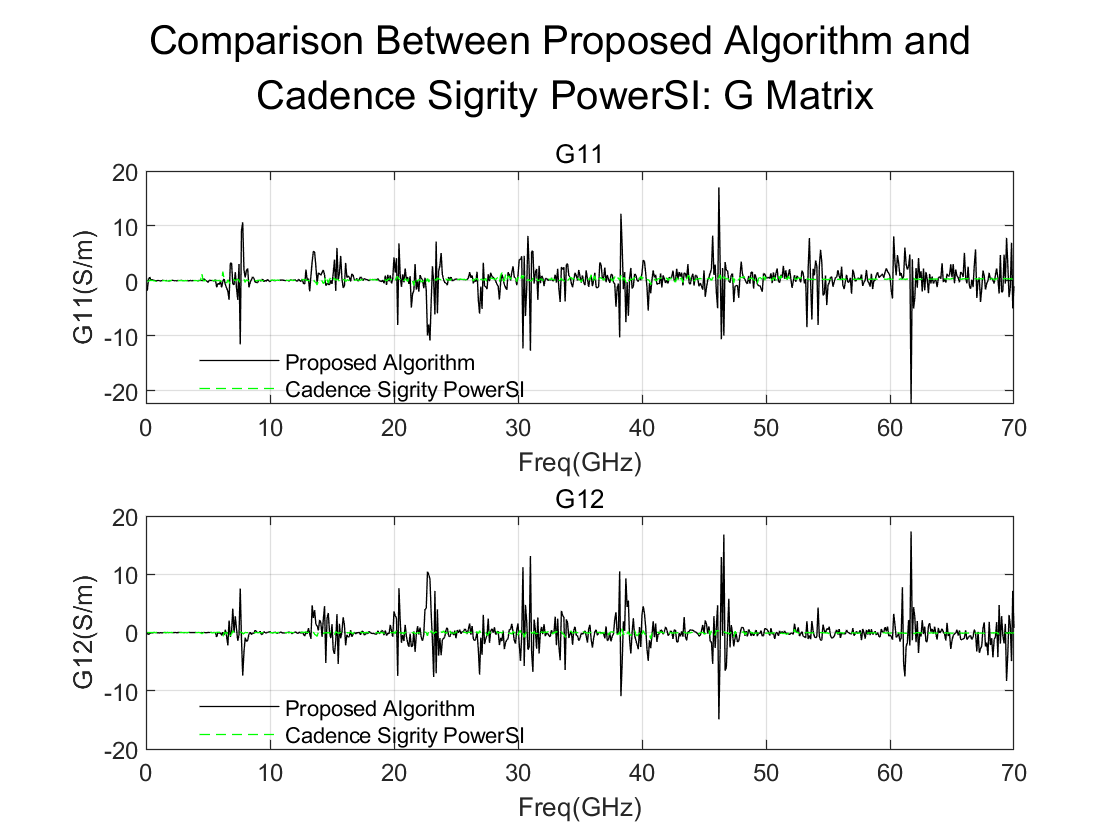


% G
figure('Name','G_noisy (compared with PowerSI)')
sgtitle({'Comparison Between Proposed Algorithm and';' Cadence Sigrity PowerSI: G Matrix'})
total = ceil(numOfLines/2);
for idx = 1:numOfLines
    subplot(2,total,idx)
    plot(freq/1e9,squeeze(rlgc_noisy.G(1,idx,:)),'k-')
    hold on
    plot(freq/1e9,squeeze(rlgc_noisy_PowerSI.G(1,idx,:)),'g--')
    hold off
    grid on
    xlabel('Freq(GHz)');
    ylabel(sprintf('G1%u(S/m)',idx));
    title(sprintf('G1%u',idx));
    legend({'Proposed Algorithm','Cadence Sigrity PowerSI'},'Location','best','NumColumns',1)
    legend('boxoff')
end

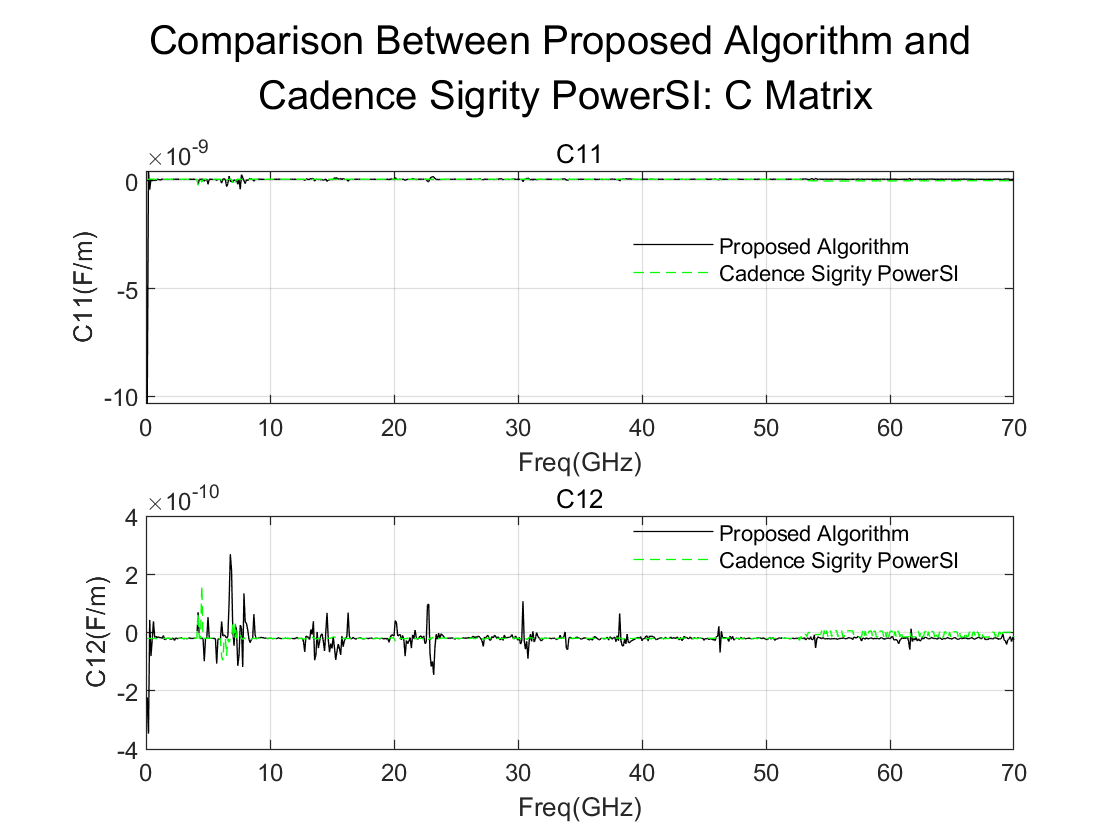


% C
figure('Name','C_noisy (compared with PowerSI)')
sgtitle({'Comparison Between Proposed Algorithm and';' Cadence Sigrity PowerSI: C Matrix'})
total = ceil(numOfLines/2);
for idx = 1:numOfLines
    subplot(2,total,idx)
    plot(freq/1e9,squeeze(rlgc_noisy.C(1,idx,:)),'k-')
    hold on
    plot(freq/1e9,squeeze(rlgc_noisy_PowerSI.C(1,idx,:)),'g--')
    hold off
    grid on
    xlabel('Freq(GHz)');
    ylabel(sprintf('C1%u(F/m)',idx));
    title(sprintf('C1%u',idx));
    legend({'Proposed Algorithm','Cadence Sigrity PowerSI'},'Location','best','NumColumns',1)
    legend('boxoff')
end

## RLGC_smooth compared with Cadence PowerSI

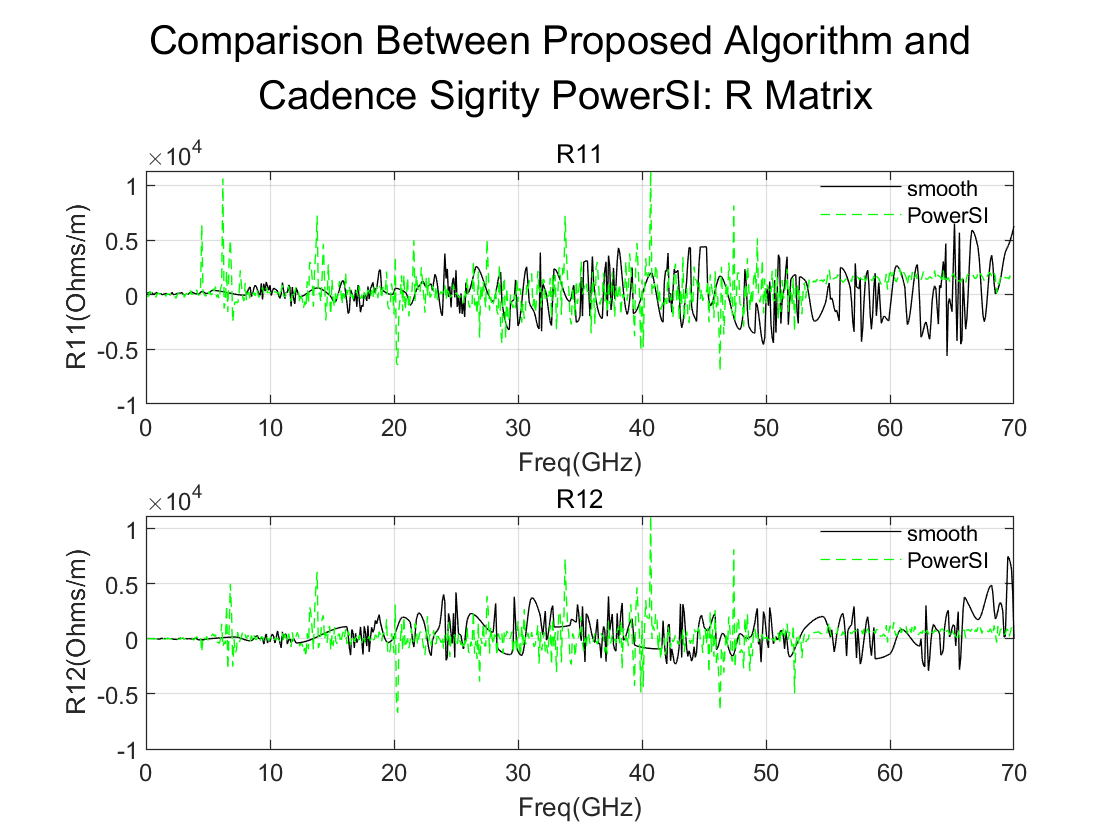

% R
figure('Name','R_noisy (compared with PowerSI)')
sgtitle({'Comparison Between Proposed Algorithm and';' Cadence Sigrity PowerSI: R Matrix'})
total = ceil(numOfLines/2);
for idx = 1:numOfLines
    subplot(2,total,idx)
    plot(freq/1e9,squeeze(rlgc_smooth.R(1,idx,:)),'k-')
    hold on
    plot(freq/1e9,squeeze(rlgc_noisy_PowerSI.R(1,idx,:)),'g--')
    hold off
    grid on
    xlabel('Freq(GHz)');
    ylabel(sprintf('R1%u(Ohms/m)',idx));
    title(sprintf('R1%u',idx));
    legend({'smooth','PowerSI'},'Location','best','NumColumns',1)
    legend('boxoff')
end

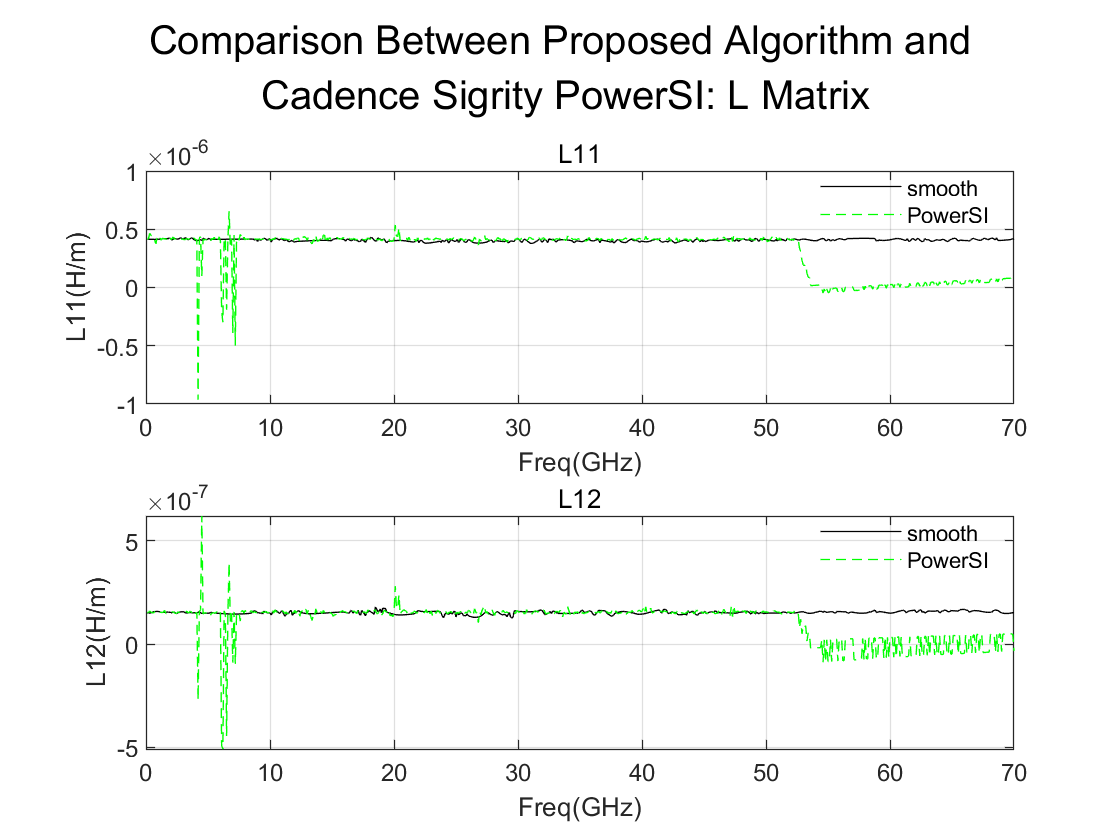


% L
figure('Name','L_noisy (compared with PowerSI)')
sgtitle({'Comparison Between Proposed Algorithm and';' Cadence Sigrity PowerSI: L Matrix'})
total = ceil(numOfLines/2);
for idx = 1:numOfLines
    subplot(2,total,idx)
    plot(freq/1e9,squeeze(rlgc_smooth.L(1,idx,:)),'k-')
    hold on
    plot(freq/1e9,squeeze(rlgc_noisy_PowerSI.L(1,idx,:)),'g--')
    hold off
    grid on
    xlabel('Freq(GHz)');
    ylabel(sprintf('L1%u(H/m)',idx));
    title(sprintf('L1%u',idx));
    legend({'smooth','PowerSI'},'Location','best','NumColumns',1)
    legend('boxoff')
end

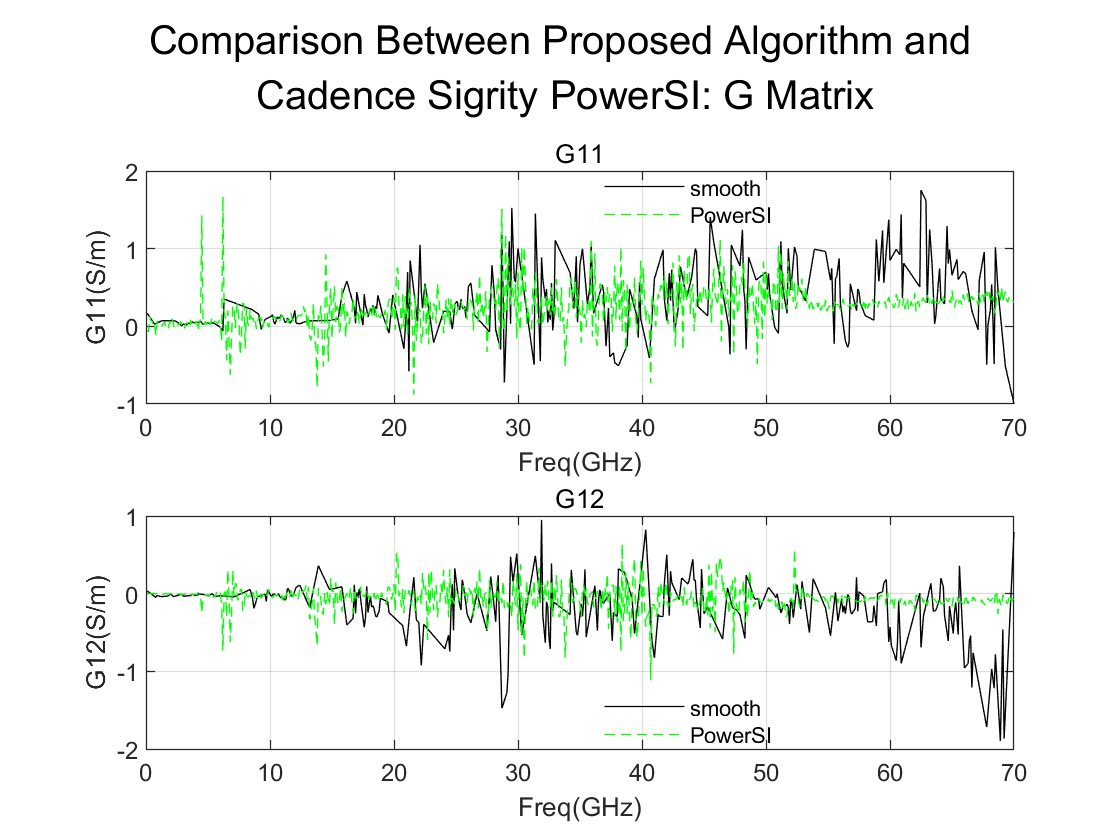


% G
figure('Name','G_noisy (compared with PowerSI)')
sgtitle({'Comparison Between Proposed Algorithm and';' Cadence Sigrity PowerSI: G Matrix'})
total = ceil(numOfLines/2);
for idx = 1:numOfLines
    subplot(2,total,idx)
    plot(freq/1e9,squeeze(rlgc_smooth.G(1,idx,:)),'k-')
    hold on
    plot(freq/1e9,squeeze(rlgc_noisy_PowerSI.G(1,idx,:)),'g--')
    hold off
    grid on
    xlabel('Freq(GHz)');
    ylabel(sprintf('G1%u(S/m)',idx));
    title(sprintf('G1%u',idx));
    legend({'smooth','PowerSI'},'Location','best','NumColumns',1)
    legend('boxoff')
end

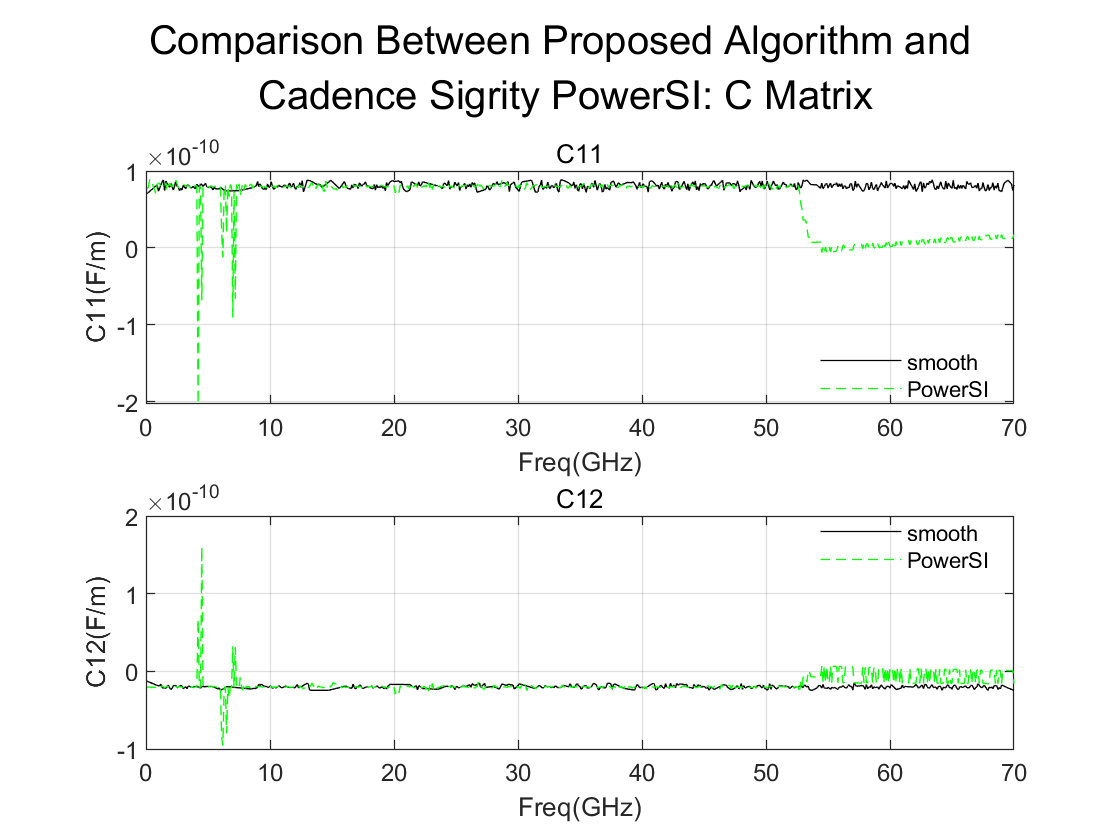


% C
figure('Name','C_noisy (compared with PowerSI)')
sgtitle({'Comparison Between Proposed Algorithm and';' Cadence Sigrity PowerSI: C Matrix'})
total = ceil(numOfLines/2);
for idx = 1:numOfLines
    subplot(2,total,idx)
    plot(freq/1e9,squeeze(rlgc_smooth.C(1,idx,:)),'k-')
    hold on
    plot(freq/1e9,squeeze(rlgc_noisy_PowerSI.C(1,idx,:)),'g--')
    hold off
    grid on
    xlabel('Freq(GHz)');
    ylabel(sprintf('C1%u(F/m)',idx));
    title(sprintf('C1%u',idx));
    legend({'smooth','PowerSI'},'Location','best','NumColumns',1)
    legend('boxoff')
end

## Comparison between smooth-S (dB) and original-S

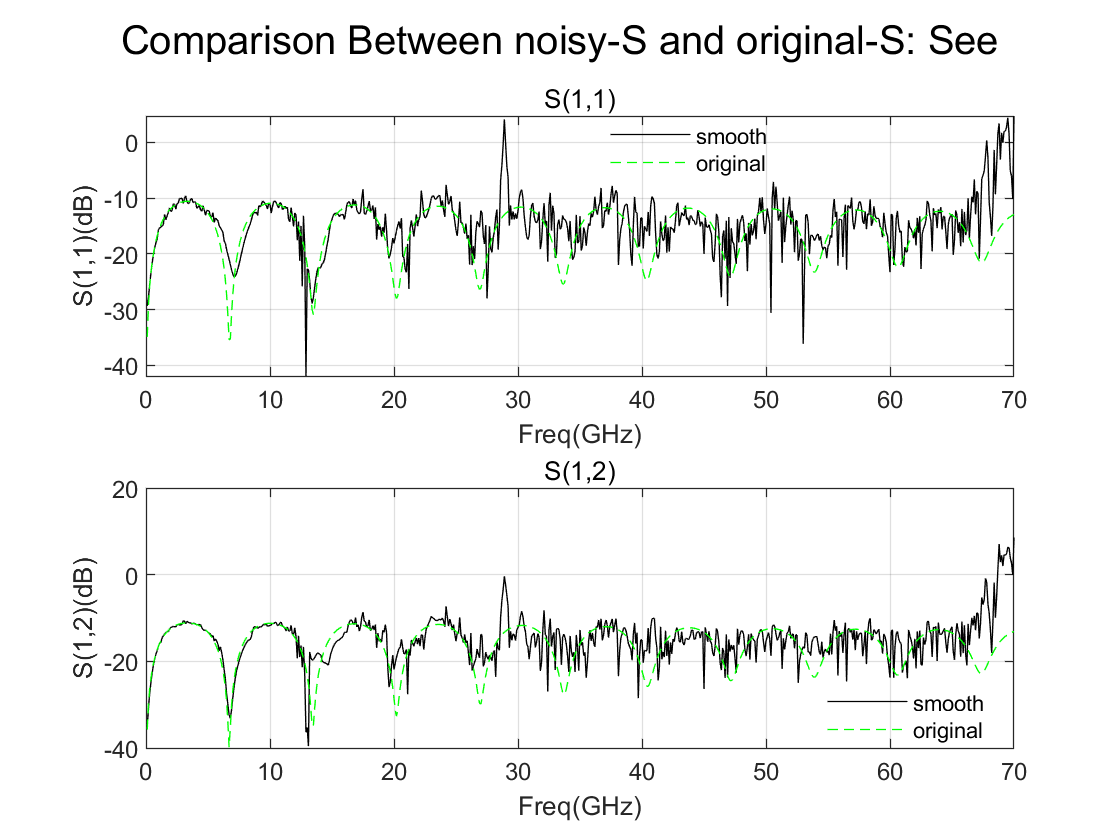

% external<-external
figure('Name','noisy-S (dB): See') 
sgtitle({'Comparison Between noisy-S and original-S: See'})
num_of_columes = ceil(numOfLines/2);
for idx = 1:numOfLines
    subplot(2,num_of_columes,idx)
    plot(freq/1e9,db(squeeze(s_rlgc_smooth(1,idx,:)),'voltage'),'k-')
    hold on
    plot(freq/1e9,db(squeeze(s_original(1,idx,:)),'voltage'),'g--')
    hold off
    grid on
    xlabel('Freq(GHz)');
    ylabel(sprintf('S(1,%u)(dB)',idx));
    title(sprintf('S(1,%u)',idx));
    legend({'smooth','original'},'Location','best','NumColumns',1)
    legend('boxoff')
end

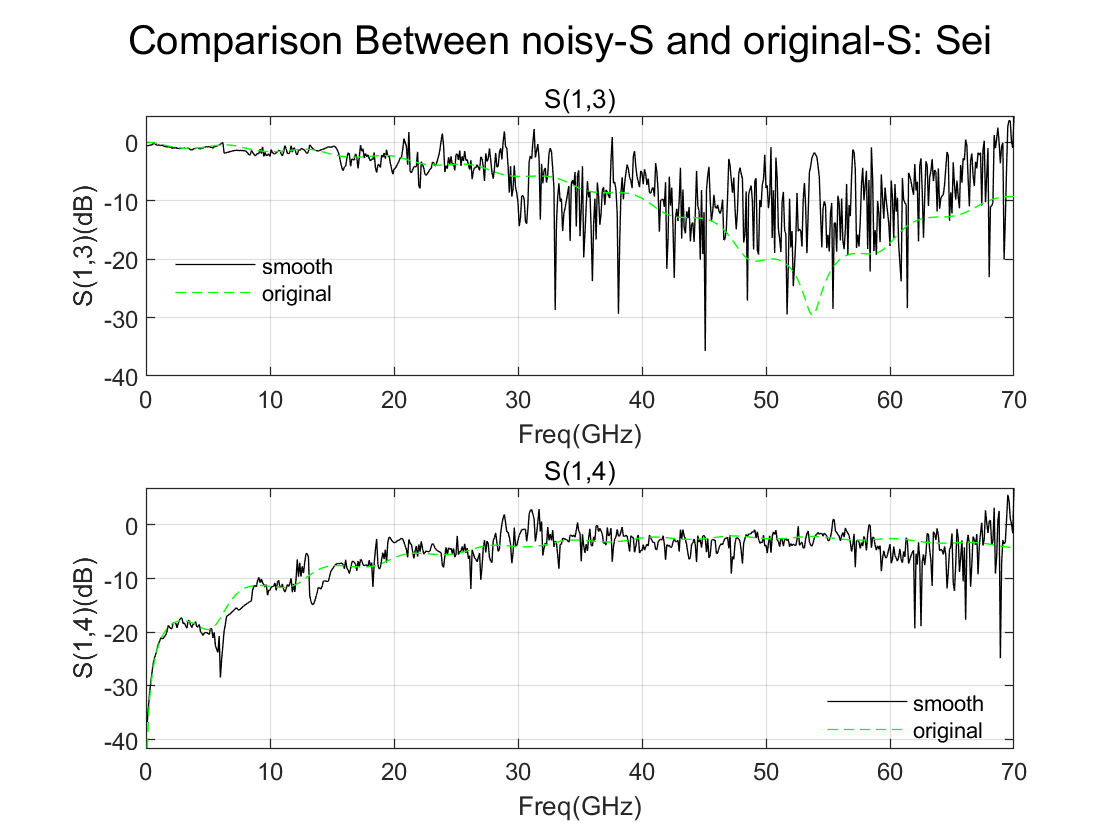


% external<-internal
figure('Name','noisy-S (dB): Sei')
sgtitle({'Comparison Between noisy-S and original-S: Sei'})
num_of_columes = ceil(numOfLines/2);
for idx = 1:numOfLines
    subplot(2,num_of_columes,idx)
    plot(freq/1e9,db(squeeze(s_rlgc_smooth(1,idx+numOfLines,:)),'voltage'),'k-')
    hold on
    plot(freq/1e9,db(squeeze(s_original(1,idx+numOfLines,:)), 'voltage'),'g--')
    hold off
    grid on
    xlabel('Freq(GHz)');
    ylabel(sprintf('S(1,%u)(dB)',idx+numOfLines));
    title(sprintf('S(1,%u)',idx+numOfLines));
    legend({'smooth','original'},'Location','best','NumColumns',1)
    legend('boxoff')
end

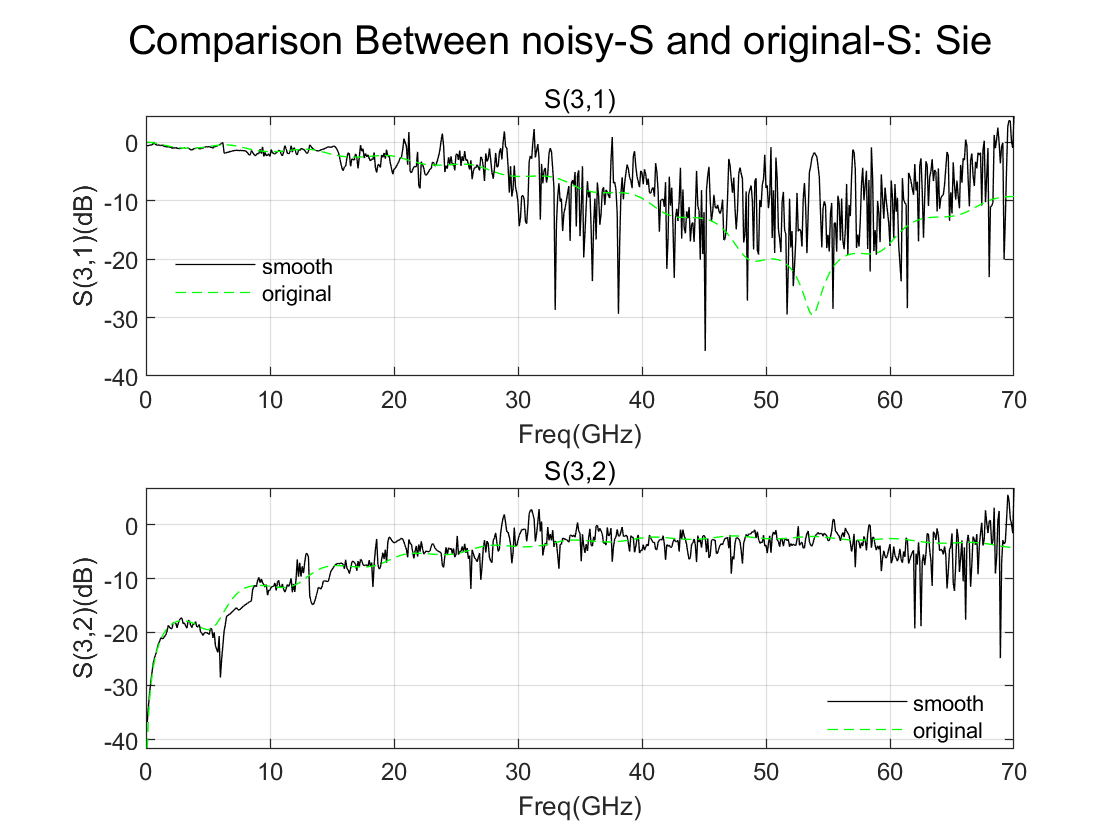


% internal<-external
figure('Name','noisy-S (dB): Sie') 
sgtitle({'Comparison Between noisy-S and original-S: Sie'})
num_of_columes = ceil(numOfLines/2);
for idx = 1:numOfLines
    subplot(2,num_of_columes,idx)
    plot(freq/1e9,db(squeeze(s_rlgc_smooth(numOfLines+1,idx,:)),'voltage'),'k-')
    hold on
    plot(freq/1e9,db(squeeze(s_original(numOfLines+1,idx,:)),'voltage'),'g--')
    hold off
    grid on
    xlabel('Freq(GHz)');
    ylabel(sprintf('S(%u,%u)(dB)',numOfLines+1,idx));
    title(sprintf('S(%u,%u)',numOfLines+1,idx));
    legend({'smooth','original'},'Location','best','NumColumns',1)
    legend('boxoff')
end

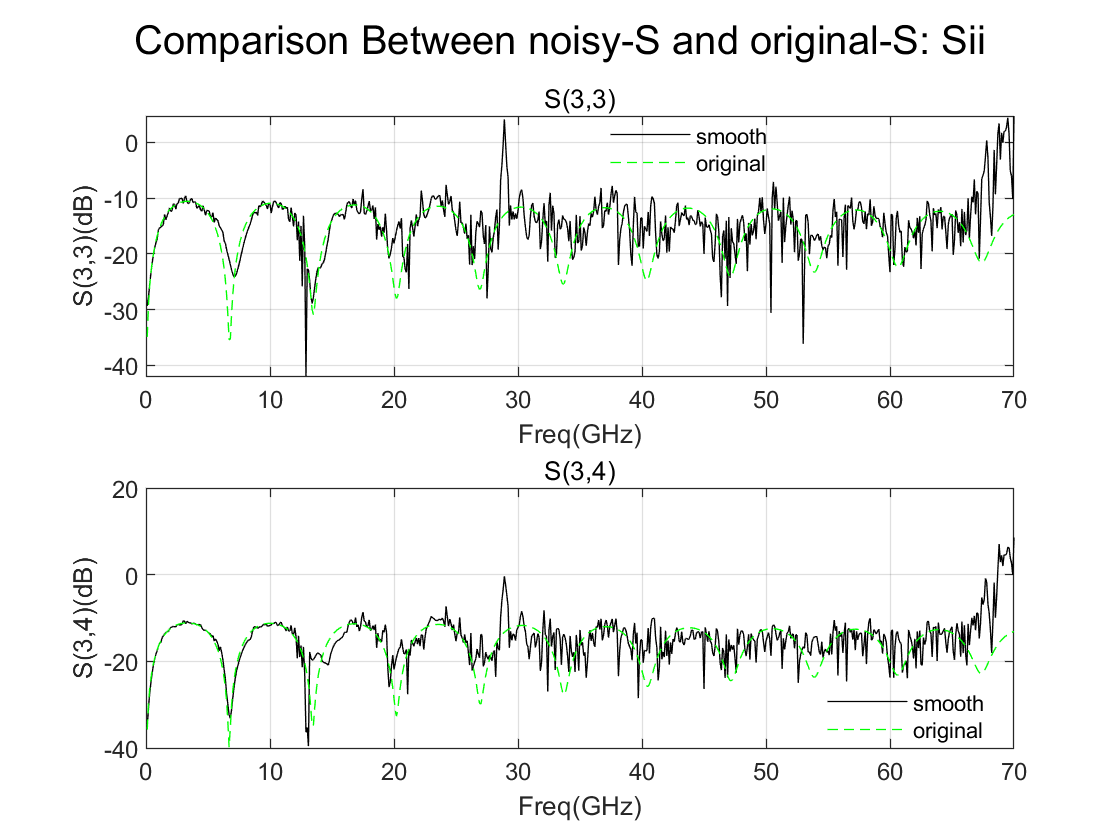


% internal<-internal
figure('Name','noisy-S (dB): Sii') 
sgtitle({'Comparison Between noisy-S and original-S: Sii'})
num_of_columes = ceil(numOfLines/2);
for idx = 1:numOfLines
    subplot(2,num_of_columes,idx)
    plot(freq/1e9,db(squeeze(s_rlgc_smooth(numOfLines+1,numOfLines+idx,:)),'voltage'),'k-')
    hold on
    plot(freq/1e9,db(squeeze(s_original(numOfLines+1,numOfLines+idx,:)),'voltage'),'g--')
    hold off
    grid on
    xlabel('Freq(GHz)');
    ylabel(sprintf('S(%u,%u)(dB)',numOfLines+1,numOfLines+idx));
    title(sprintf('S(%u,%u)',numOfLines+1,numOfLines+idx));
    legend({'smooth','original'},'Location','best','NumColumns',1)
    legend('boxoff')
end

## Smooth function

### R

function [Rdata_smooth] = Rsmooth(data_noisy)
Rdata_noisy = squeeze(data_noisy);

% 填充离群值
[Rdata_cleaned,outlierIndices,thresholdLow,thresholdHigh] = ...
    filloutliers(Rdata_noisy,'pchip','movmedian',100,'ThresholdFactor',0.5);

% 显示结果
clf
plot(Rdata_noisy,'Color',[109 185 226]/255,'DisplayName','输入数据')
hold on
plot(Rdata_cleaned,'Color',[0 114 189]/255,'LineWidth',1.5,'DisplayName','清理的数据')

% 绘制离群值
plot(find(outlierIndices),Rdata_noisy(outlierIndices),'x',...
    'Color',[64 64 64]/255,'DisplayName','离群值')
title(['离群值数: ' num2str(nnz(outlierIndices))])

% 绘制填充的离群值
plot(find(outlierIndices),Rdata_cleaned(outlierIndices),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','填充的离群值')

% 绘制离群值阈值
plot([(1:numel(Rdata_noisy))'; missing; (1:numel(Rdata_noisy))'],...
    [thresholdHigh(:); missing; thresholdLow(:)],'Color',[145 145 145]/255,...
    'DisplayName','离群值阈值')

hold off
legend
clear outlierIndices thresholdLow thresholdHigh

Rdata_smooth = Rdata_cleaned;
end

### L

function [Ldata_smooth] = Lsmooth(data_noisy)
Ldata_noisy = squeeze(data_noisy);

% 填充离群值
[Ldata_cleaned,outlierIndices2,thresholdLow2,thresholdHigh2] = ...
    filloutliers(Ldata_noisy,'makima','movmedian',100,'ThresholdFactor',0.5);

% 显示结果
clf
plot(Ldata_noisy,'Color',[109 185 226]/255,'DisplayName','输入数据')
hold on
plot(Ldata_cleaned,'Color',[0 114 189]/255,'LineWidth',1.5,'DisplayName','清理的数据')

% 绘制离群值
plot(find(outlierIndices2),Ldata_noisy(outlierIndices2),'x',...
    'Color',[64 64 64]/255,'DisplayName','离群值')
title(['离群值数: ' num2str(nnz(outlierIndices2))])

% 绘制填充的离群值
plot(find(outlierIndices2),Ldata_cleaned(outlierIndices2),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','填充的离群值')

% 绘制离群值阈值
plot([(1:numel(Ldata_noisy))'; missing; (1:numel(Ldata_noisy))'],...
    [thresholdHigh2(:); missing; thresholdLow2(:)],'Color',[145 145 145]/255,...
    'DisplayName','离群值阈值')

hold off
legend
clear outlierIndices2 thresholdLow2 thresholdHigh2

Ldata_smooth = Ldata_cleaned;

% % 对输入数据进行平滑处理
% Ldata_smooth = smoothdata(Ldata_cleaned,'rlowess','SmoothingFactor',0.8);
% 
% % 显示结果
% clf
% plot(Ldata_cleaned,'Color',[109 185 226]/255,'DisplayName','输入数据')
% hold on
% plot(Ldata_smooth,'Color',[0 114 189]/255,'LineWidth',1.5,'DisplayName','平滑数据')
% hold off
% legend
end

### G

function [Gdata_smooth] = Gsmooth(data_noisy)
Gdata_noisy = squeeze(data_noisy);

% 填充离群值
[Gdata_cleaned,outlierIndices6,thresholdLow6,thresholdHigh6] = ...
    filloutliers(Gdata_noisy,'linear','movmedian',50,'ThresholdFactor',0.5);

% 显示结果
clf
plot(Gdata_noisy,'Color',[109 185 226]/255,'DisplayName','输入数据')
hold on
plot(Gdata_cleaned,'Color',[0 114 189]/255,'LineWidth',1.5,'DisplayName','清理的数据')

% 绘制离群值
plot(find(outlierIndices6),Gdata_noisy(outlierIndices6),'x',...
    'Color',[64 64 64]/255,'DisplayName','离群值')
title(['离群值数: ' num2str(nnz(outlierIndices6))])

% 绘制填充的离群值
plot(find(outlierIndices6),Gdata_cleaned(outlierIndices6),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','填充的离群值')

% 绘制离群值阈值
plot([(1:numel(Gdata_noisy))'; missing; (1:numel(Gdata_noisy))'],...
    [thresholdHigh6(:); missing; thresholdLow6(:)],'Color',[145 145 145]/255,...
    'DisplayName','离群值阈值')

hold off
legend
clear outlierIndices6 thresholdLow6 thresholdHigh6

Gdata_smooth = Gdata_cleaned;

% % 对输入数据进行平滑处理
% Gdata_smooth = smoothdata(Gdata_cleaned,...
%     'rlowess','SmoothingFactor',0.8500000000000001);
% 
% % 显示结果
% clf
% plot(Gdata_cleaned,'Color',[109 185 226]/255,'DisplayName','输入数据')
% hold on
% plot(Gdata_smooth,'Color',[0 114 189]/255,'LineWidth',1.5,'DisplayName','平滑数据')
% hold off
% legend
end


### C

function [Cdata_smooth] = Csmooth(data_noisy)
Cdata_noisy = squeeze(data_noisy);

% 填充离群值
[Cdata_cleaned,outlierIndices5,thresholdLow5,thresholdHigh5] = ...
    filloutliers(Cdata_noisy,'linear','quartiles','ThresholdFactor',0.5);

% 显示结果
clf
plot(Cdata_noisy,'Color',[109 185 226]/255,'DisplayName','输入数据')
hold on
plot(Cdata_cleaned,'Color',[0 114 189]/255,'LineWidth',1.5,'DisplayName','清理的数据')

% 绘制离群值
plot(find(outlierIndices5),Cdata_noisy(outlierIndices5),'x',...
    'Color',[64 64 64]/255,'DisplayName','离群值')
title(['离群值数: ' num2str(nnz(outlierIndices5))])

% 绘制填充的离群值
plot(find(outlierIndices5),Cdata_cleaned(outlierIndices5),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','填充的离群值')

% 绘制离群值阈值
plot([xlim missing xlim],[thresholdLow5*[1 1] NaN thresholdHigh5*[1 1]],...
    'Color',[145 145 145]/255,'DisplayName','离群值阈值')

hold off
legend
clear outlierIndices5 thresholdLow5 thresholdHigh5

Cdata_smooth = Cdata_cleaned;

% % 对输入数据进行平滑处理
% Cdata_smooth = smoothdata(Cdata_cleaned,'rlowess','SmoothingFactor',0.8);
% 
% % 显示结果
% clf
% plot(Cdata_cleaned,'Color',[109 185 226]/255,'DisplayName','输入数据')
% hold on
% plot(Cdata_smooth,'Color',[0 114 189]/255,'LineWidth',1.5,'DisplayName','平滑数据')
% hold off
% legend
end